# Chapter 2 ATAP Exercises

## Chebyshev Points and Interpolants

#### Mason Mault June 2025

Exercises worked

Exercise 2.1: Chebyshev interpolants through random data 

Exercise 2.5: Convergence of Chebyshev Interpolants

Exercise 2.7: Chebyshev points scaled to the interval [a, b]

**Exercise 2.1: Chebyshev interpolants through random data **

Repeat the in text experiment of interpolating random data of varying degrees. Determine the extreme values of each interpolant, measure the run time, and plot each. For the largest degree interpolant, zoom into the interval [0.9999, 1] and count the grid points.

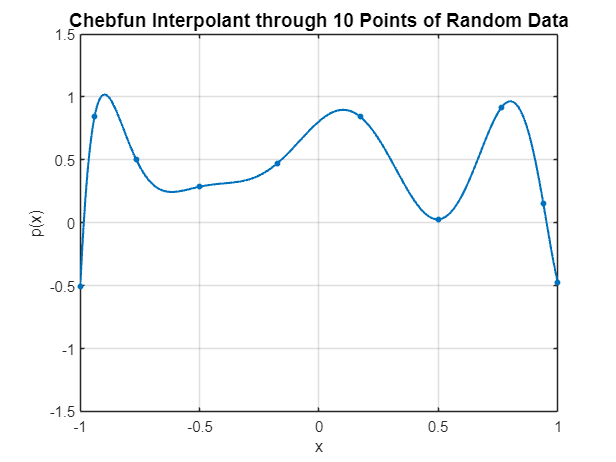

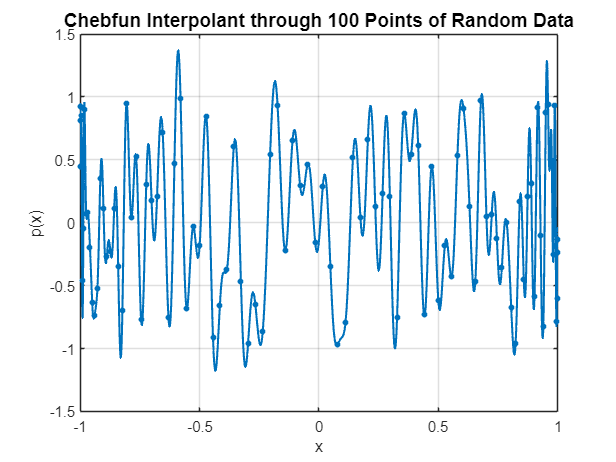

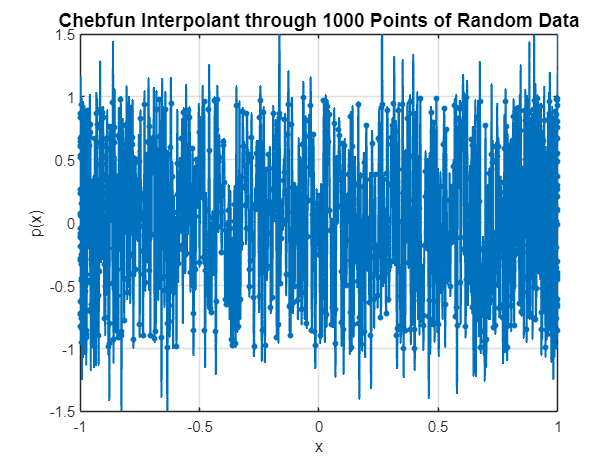

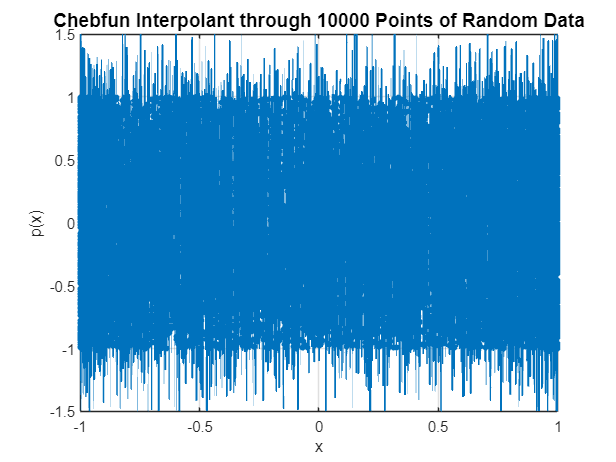

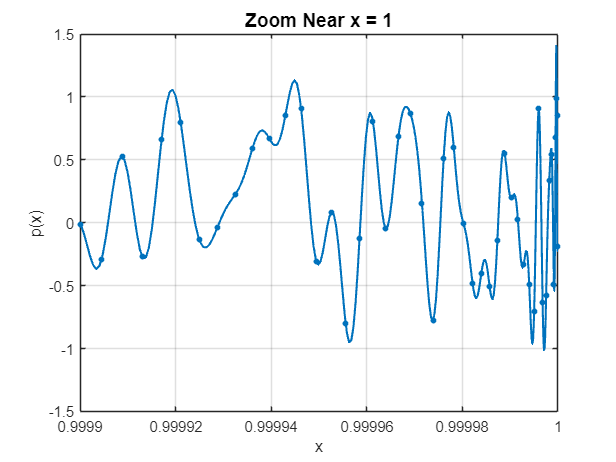

deg = [10, 100, 1000, 10000];


minMax = zeros(length(deg), 2);
runTimes = zeros(length(deg), 1);

for i = 1:length(deg)
    tic
    p = chebfun(2*rand(deg(i),1) - 1);
    minMax(i,:) = minandmax(p);
    runTimes(i) = toc;

    figure(i)
     plot(p, '.-', 'LineWidth', 1.4, 'MarkerSize', 12)
    title(sprintf('Chebfun Interpolant through %d Points of Random Data', deg(i)), ...
        'FontSize', 13)
    xlabel('x', 'FontSize', 11)
    ylabel('p(x)', 'FontSize', 11)
    grid on
    ylim([-1.5, 1.5]) 

    if i == length(deg)
        figure(i + 1)
        plot(p, '.-', 'LineWidth', 1.4, 'MarkerSize', 12)
        title('Zoom Near x = 1', 'FontSize', 13)
        xlabel('x', 'FontSize', 11)
        ylabel('p(x)', 'FontSize', 11)
        xlim([0.9999, 1])
        grid on
    end
end

runTimes

runTimes =     0.0115
    0.0050
    0.1370
    3.6041


and I counted 46 Chebpts inside the interval [0.9999, 1].

**Exercise 2.5: Convergence of Chebyshev Interpolants**

Analyze the error as a function of $n$ for $f\left(x\right)=e^x$, then repeat this analysis for the Runge function.

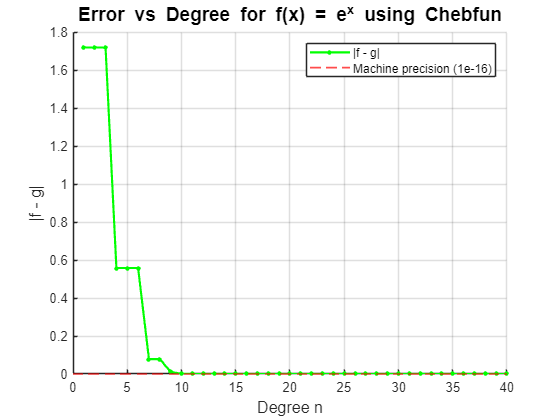

% build exponential function
x = chebfun('x');
f = exp(x);

% initialize n values on log scale
degs = round(logspace(0, 3, 40));
errs = zeros(size(degs));

% compute |f - g| per degree for f = e^x
% where g is the chebyshev interpolant of degree n
for k = 1:length(degs)
    n = degs(k);
    g = chebfun(f, n);
    errs(k) = norm(f - g, inf);
end

% plot |f - g| vs degree for exponential function
figure
hold on

semilogy(errs, '.-', 'LineWidth', 1.6, 'MarkerSize', 10)
yline(1e-16, 'r--', 'LineWidth', 1.2)

xlabel('Degree n', 'FontSize', 12)
ylabel('|f - g|', 'FontSize', 12)
title('Error vs Degree for f(x) = e^x using Chebfun', 'FontSize', 14)

legend({'|f - g|', 'Machine precision (1e-16)'}, 'Location', 'northeast')
grid on

For the exponential function, the Chebyshev interpolant approximates f(x) to machine precision around

n = 16 degrees. Past this point, the error stabilizes.

Repeat the same procedure for the Runge function

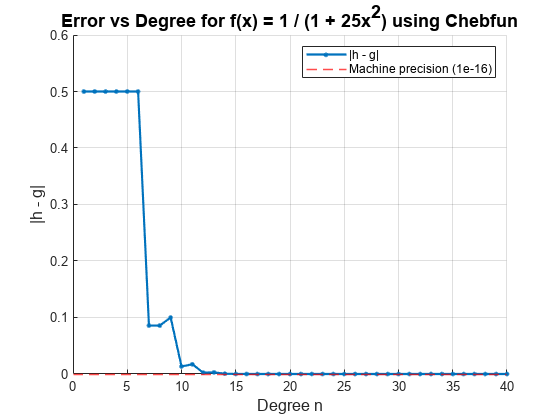

% build Runge function
h = 1/(1 + x^2);

% initialize n values on log scale
degs2 = round(logspace(0, 3, 40));
errs2 = zeros(size(degs2));

% compute |h - g| per degree for Runge function
for k = 1:length(degs2)
    n = degs2(k);
    g = chebfun(h, n);
    errs2(k) = norm(h - g, inf);
end

% plot |h - g| vs degree for Runge function
figure
hold on

semilogy(errs2, '.-', 'LineWidth', 1.6, 'MarkerSize', 10)
yline(1e-16, 'r--', 'LineWidth', 1.2)

xlabel('Degree n', 'FontSize', 12)
ylabel('|h - g|', 'FontSize', 12)
title('Error vs Degree for f(x) = 1 / (1 + 25x^2) using Chebfun', 'FontSize', 14)

legend({'|h - g|', 'Machine precision (1e-16)'}, 'Location', 'northeast')
grid on

For the Runge function, the Chebyshev interpolant approximates it to machine precision around n = 22 degrees, with the same error pattern (stability) occuring past this point.

**Exercise 2.7: Chebyshev points scaled to the interval [a, b]**

Build 10 Chebyshev points on [-1, 1]

pts = chebpts(10, [-1 1]);
disp(pts)

   -1.0000
   -0.9397
   -0.7660
   -0.5000
   -0.1736
    0.1736
    0.5000
    0.7660
    0.9397
    1.0000



Build a 9 degree interpolant of sin(x) on [-1, 1], and compare it to sin(x) on [-6, 6]

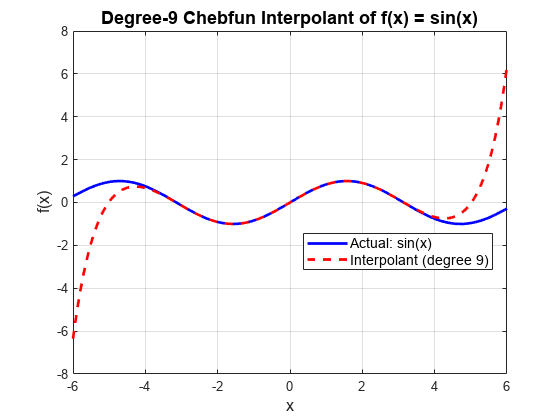

% build 9 degree interpolant of sin(x) at 10 points on [-1 1]
fActual = @(x) sin(x);
fInterp = chebfun(@sin, 10);

% x values for plotting on [-6, 6]
xx = linspace(-6, 6, 1000);

figure
plot(xx, fActual(xx), 'b-', 'LineWidth', 2)
hold on
plot(xx, fInterp(xx), 'r--', 'LineWidth', 2)

title('Degree-9 Chebfun Interpolant of f(x) = sin(x)', 'FontSize', 14)
xlabel('x', 'FontSize', 12)
ylabel('f(x)', 'FontSize', 12)
legend({'Actual: sin(x)', 'Interpolant (degree 9)'}, 'FontSize', 11, 'Location', 'best')
grid on

Build a semilog plot of the error between p(x) and sin(x) on [-6, 6]

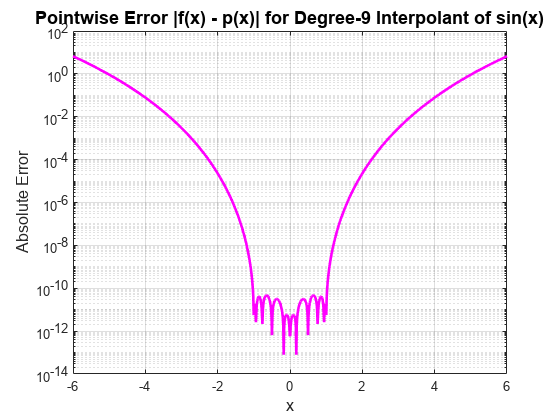

% |fActual - fInterp| vs [-6,6] plot
errs3 = abs(fActual(xx) - fInterp(xx));

figure
semilogy(xx, errs3, 'm-', 'LineWidth', 2)

title('Pointwise Error |f(x) - p(x)| for Degree-9 Interpolant of sin(x)', 'FontSize', 14)
xlabel('x', 'FontSize', 12)
ylabel('Absolute Error', 'FontSize', 12)

grid on

Build 10 Chebyshev points on [0, 6]

pts2 = chebpts(10, [0,6]);
disp(pts2)

         0
    0.1809
    0.7019
    1.5000
    2.4791
    3.5209
    4.5000
    5.2981
    5.8191
    6.0000



Again build 9 degree interpolant of sin(x), this time at points [0, 6], and compare it to sin(x) on [-6, 6]

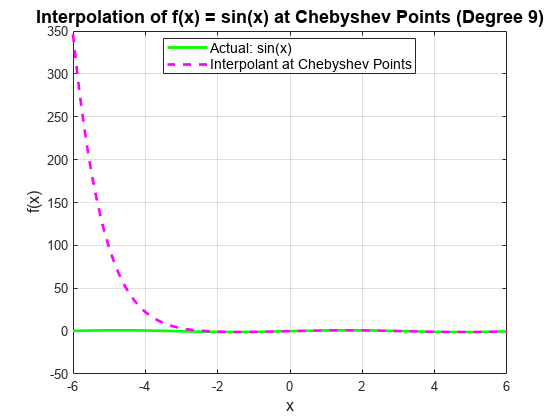

fInterp2 = chebfun(fActual, [0 6], 10);

figure
plot(xx, fActual(xx), '-g', 'LineWidth', 2)
hold on
plot(xx, fInterp2(xx), '--m', 'LineWidth', 2)

title('Interpolation of f(x) = sin(x) at Chebyshev Points (Degree 9)', 'FontSize', 14)
xlabel('x', 'FontSize', 12)
ylabel('f(x)', 'FontSize', 12)

legend({'Actual: sin(x)', 'Interpolant at Chebyshev Points'}, 'FontSize', 11, 'Location', 'best')
grid on

Build a semilog plot of the error between p2(x) and sin(x) on [-6, 6]

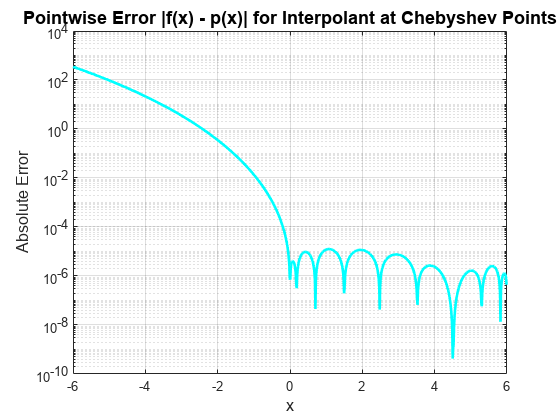

errs4 = abs(fActual(xx) - fInterp2(xx));

figure
semilogy(xx, errs4, 'c-', 'LineWidth', 2)

title('Pointwise Error |f(x) - p(x)| for Interpolant at Chebyshev Points', 'FontSize', 14)
xlabel('x', 'FontSize', 12)
ylabel('Absolute Error', 'FontSize', 12)

grid on

fInterp1 is the Chebyshev interpolation built on [-1, 1], fInterp2 the interpolation built on [0, 6].

Both interpolations perform well in their defined domain, while fInterp1 does a better job overall. 

I assume this has to do with its interval being centered about 0, giving symmetric weight rather than "more weight" to the points on the right of the interval like fInterp2 does. 